%{
Data from 
https://cdiac.ess-dive.lbl.gov/trends/emis/tre_glob_2014.html
With first two (text) lines removed. 

The data is in MtC, converting to GtC requires dividing
by 1000; this is done manually when the 'data' array is
used.

DON'T USE DATA FROM global.1751_2014.csv
%}

## DON'T USE DATA FROM global.1751_2014.csv

data = csvread('Documents/prelim/global.1751_2014.csv');

cdiacFFuel = csvread('Sociodynamics/data/cdiac_fossilfuel.csv');
cdiacland  = csvread('Sociodynamics/data/cdiac_landuse_no_header.csv');

% Lin. extrapolate cdiacland data from 1850-1900 to 1800-1850 and 1850-1900
co2Land1850 = cdiacland(1,2);
co2Land1900 = cdiacland(50,2);
co2Land1800 = 2*co2Land1850 - co2Land1900

co2Land1800 = 275.4000


% lin. extrapolate cdiacland data from 1955-2005 to get 2005 to 2014
co2Land1955 = cdiacland(105,2);
co2Land2005 = cdiacland(end,2);
co2Land2014 = (9/50)*(co2Land2005 - co2Land1955) + co2Land2005

co2Land2014 = 1.4911e+03


co2LandMod = [1800, co2Land1800; cdiacland(:,[1,2]); 2014, co2Land2014];

% Total emissions based on Tom's analysis
co2Total = co2LandMod(2:end-1, 2) + cdiacFFuel(100:255, 2);
size(co2Total)

ans =    156     1


co2Total(1,:)

ans = 554.6000

tvals = co2LandMod(:,1);
tvals(end-1)

ans = 2005

co2Total = [tvals(1), co2LandMod(1,2)+cdiacFFuel(50,2); tvals(2:end-1),co2Total(:,:); tvals(end),co2LandMod(end,2)+cdiacFFuel(end,2) ]

co2Total = 	1.0e+04 *

    0.1800    0.0283
    0.1850    0.0555
    0.1851    0.0547
    0.1852    0.0605
    0.1853    0.0606
    0.1854    0.0614
    0.1855    0.0613
    0.1856    0.0624
    0.1857    0.0630
    0.1858    0.0637


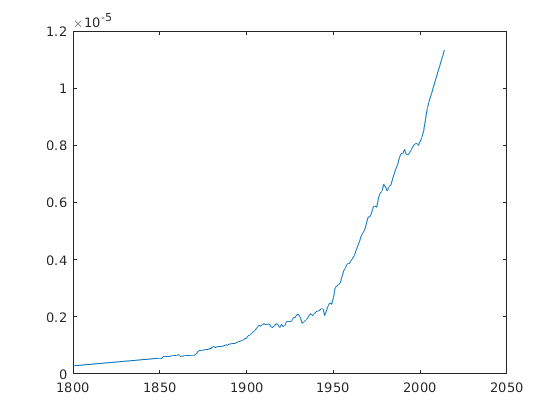

plot(data(:,1), data(:,2)./1000);

size(co2Total)

ans =    158     2


co2Total(end)./1000

ans = 11.3461

co2Total(:,2) = co2Total(:,2)./1000;
csvwrite('Sociodynamics/data/co2TotalEmissions.csv', co2Total)

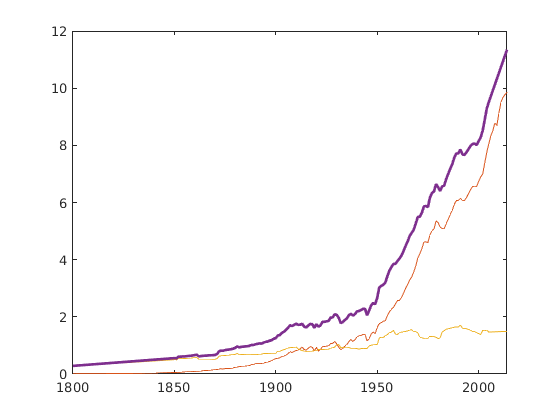

plot(cdiacland(:,1), cdiacland(:,2)./1000)
hold on
plot(cdiacFFuel(:,1), cdiacFFuel(:,2)./1000)
plot(co2LandMod(:,1), co2LandMod(:,2)./1000)
plot(co2Total(:,1), (co2Total(:,2))./1000 , 'LineWidth', 2)
xlim([1800,2014])
hold off

size(data)

ans =    264     8


s_ = 50;
eps_max = 7;
t = 2014:1:2200;
% Note that data is being divided by 1000 s.t. MtC -> GtC
post_2014 = baseline_CO2_emis(t, data(264,2)./1000, eps_max, s_);

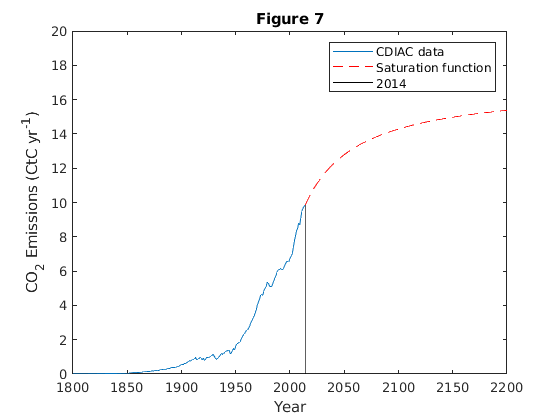

hold on
plot(t, post_2014, '--r')
ylim([0,20])
xlim([1800, 2200])
ylabel('CO_2 Emissions (CtC yr^{-1})')
xlabel('Year')
line([2014, 2014], [0, data(264,2)./1000], 'Color','black')
legend('CDIAC data', 'Saturation function', '2014')
title('Figure 7')

function emissions__ = baseline_CO2_emis(t, epsilon_2014, epsilon_max, s)
    % Computes baseline CO2 emissions in absence of mitigation
    %{
    
    %}
    emissions__ = epsilon_2014 + ((t-2014).*epsilon_max)./(t - 2014 + s);
end
